# Thermal Model of a House - Worksheet

This example shows how to use Simulink® to create the thermal model of a house. This system models the outdoor environment, the thermal characteristics of the house, and the house heating system.

The [`sldemo_househeat_data.m`](matlab:cd(setupExample('simulink_general/sldemo_househeatExample'));edit('sldemo_househeat_data.m')) file initializes data in the model workspace. To make changes, you can edit the model workspace directly or edit the file and reload the model workspace. To view the model workspace, from the Simulink Editor, on the **Modeling** tab, in the **Design** section, click **Model Explorer**.

## Task 1. Open the house heat model

Open the `sldemo_househeat` model.

mdl='sldemo_househeatWorksheet'; %house heat model is named as sldemo_househeat
open_system(mdl);

## Task 2. Initialize Model

This model calculates heating costs for a generic house. Opening the model loads the information about the house from the `sldemo_househeat_data.mlx` file. The file:

- Defines the house geometry: size and number of windows

- Specifies the thermal properties of house materials

- Calculates the thermal resistance of the house

- Provides the heater characteristics: hot air temperature and flow-rate

- Defines the cost of electricity: $0.09/kWhr

- Specifies the initial room temperature: 20 ºC = 68 ºF

open sldemo_househeat_data.mlx

## Task 3. Model Components

### **Task 3.1 Insert a Constant Block**

**Set Point**

From the `Simulink Library`, insert a `Constant Block` and name it as `Set Point` and specify the temperature that must be maintained indoors. 

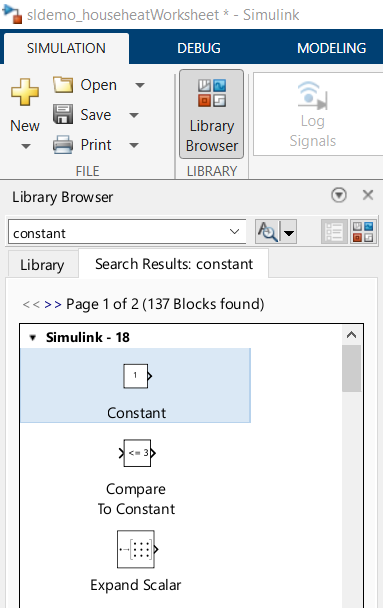

### **Task 3.2 Connect the Set Point block to Fahrenheit to Celsius block**

**Fahrenheit to Celsius block**

By default, define the `Set Point` as `70 ºF`. Temperatures are given in `ºF`. The model converts the temperature to `ºC`. Connect the `Set Point` to the `Fahrenheit to Celsius block`.

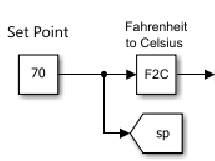

### **Task 3.3 Add a Knob block**

From the `Simulink Library`, insert a Knob` Block.`

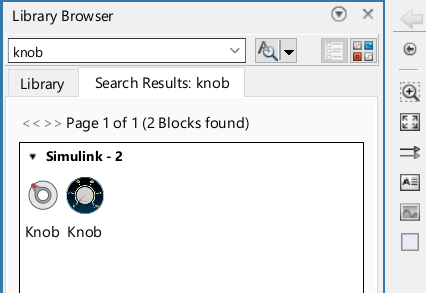 

A `Knob tab` will appear right next to the Apps tab. Next, click `Connect` so we can connect it to our `Set Point`. This option provides the end-user to change the value of the `Set Point block `without opening it.

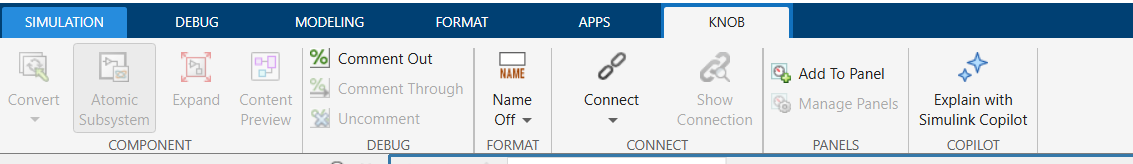

## **Task 4. The Thermostat**

**Add a Relay block**

Open the `Thermostat` subsystem by running the code below or double-clicking the `Thermostat subsystem `from the `Simulink Model.`

open_system([mdl,'/Thermostat']);

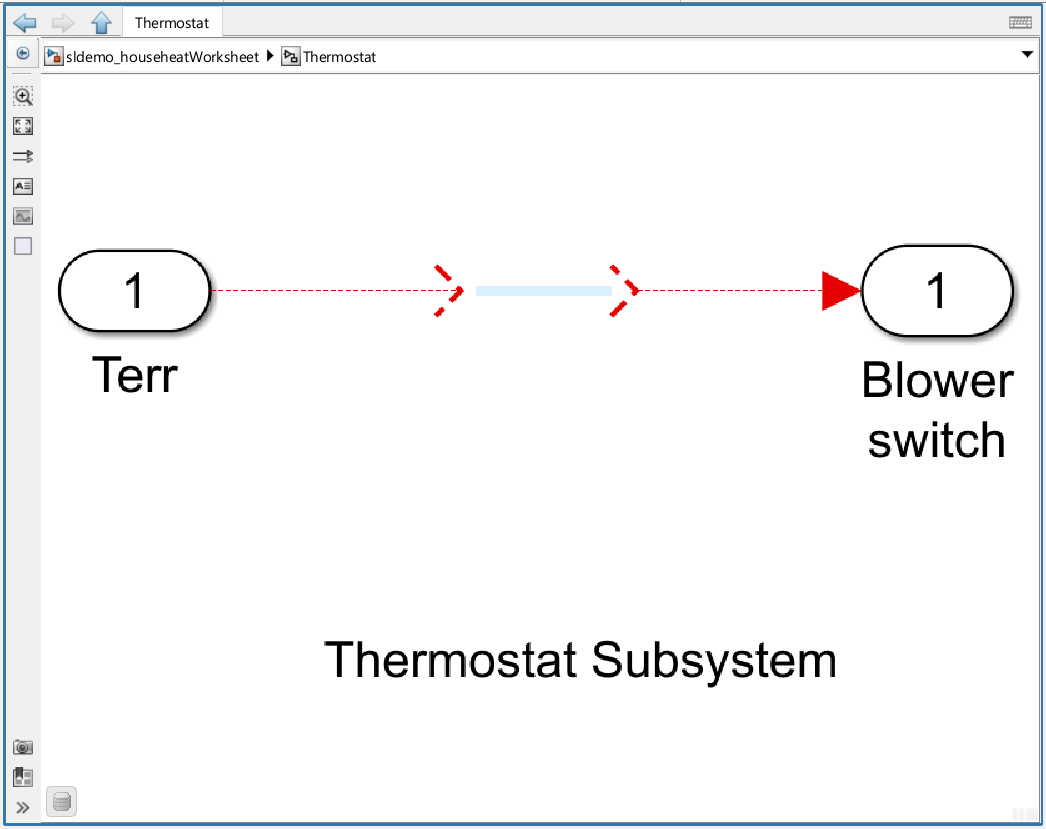

Insert a `Relay block`. 

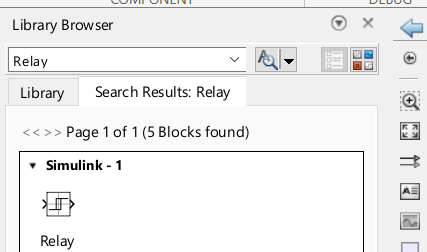

The thermostat allows fluctuations of 5 ºF above or below the desired room temperature. If air temperature drops below 65 ºF, the thermostat turns on the heater.

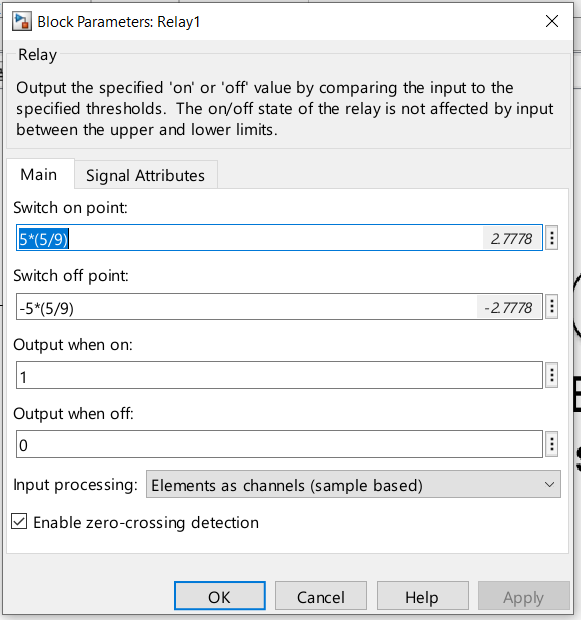

Connect the `Terr inport` as input and the `Blower switch outport` as output to the `Relay block.`

## **Task 5. The Heater**

**Add a Gain block**

The `Heater subsystem` models a constant air flow rate, `Mdot`, is specified in the `sldemo_househeat_data.m` file. The thermostat signal turns the heater on or off. When the heater is on, it blows hot air at temperature `THeater` (50 ºC = 122 ºF by default) at a constant flow rate of `Mdot` (1kg/sec = 3600kg/hr by default). This equation expresses the heat flow into the room.


$$\frac{dQ}{dt}=\left( T_{heater} - T_{room} \right) \cdot Mdot \cdot c$$



$$\frac{dQ}{dt} = \mbox{ heat flow from the heater into the room}$$



$$c = \mbox{ heat capacity of air at constant pressure}$$



$$Mdot = \mbox{ air mass flow rate through heater (kg/hr)}$$



$$T_{heater} = \mbox{ temperature of hot air from heater}$$



$$T_{room} = \mbox{ current room air temperature}$$


Open the `Heater`** subsystem**.

open_system([mdl,'/Heater']);

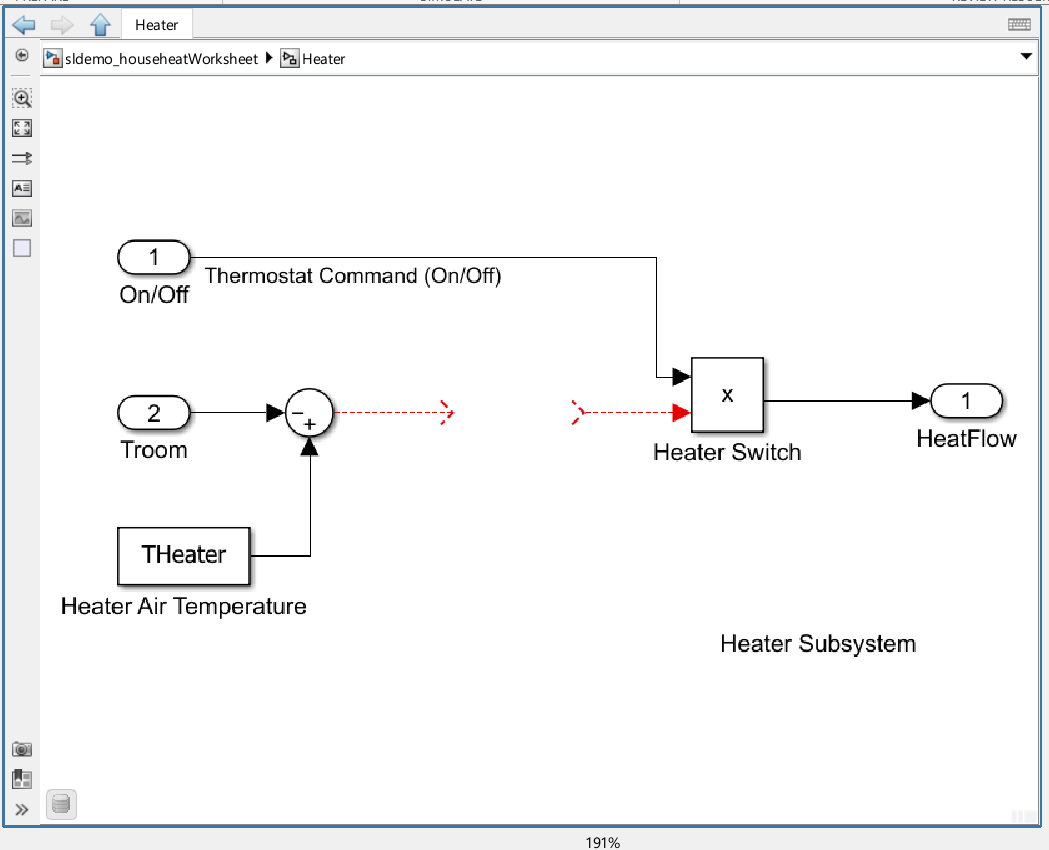

Insert a `Gain block `and name it as `HeatGain. `

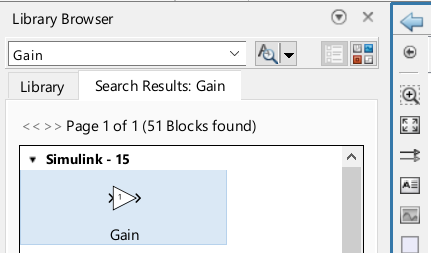

Define the `HeatGain `equal to `Mdot*c.`

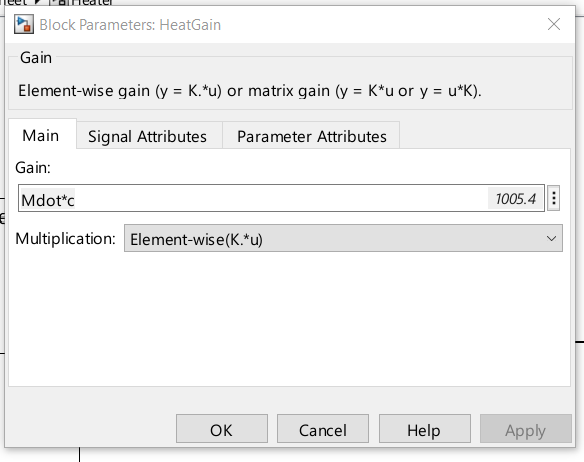

Connect the `Sum2 block` as input and the `Heater switch` as output to the `HeatGain block.`

## **Task 6. The Cost Calculator**

**Cost Calculator**

The `Cost Calculator` is a `Gain block` that integrates the heat flow over time and multiplies it by the energy cost. The model plots the heating cost in the `PlotResults` scope.

Insert a `Gain block `and name it as `Cost Calculator. `Define the value equal to `cost.`

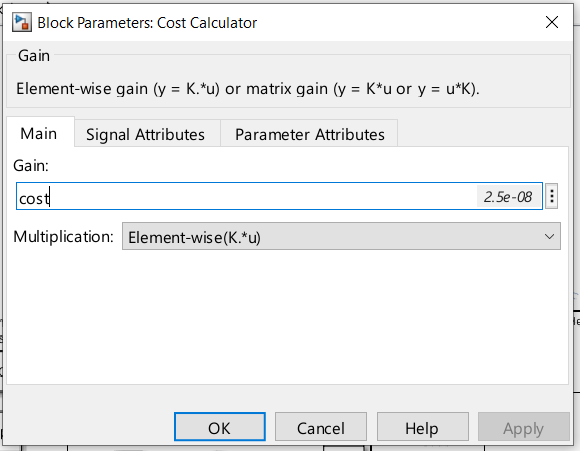

Connect the `Integrator block `as input and `HeatCost `as output.

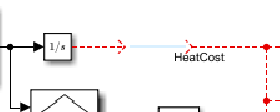

**House**

The `House` is a subsystem that calculates room temperature variations. It takes into consideration the heat flow from the heater and heat losses to the environment. This equation expresses the heat losses and the temperature time derivative.


$$\left( \frac{dQ}{dt} \right) _{losses} = \frac{T_{room}-T_{out}}{R_{eq}}$$



$$\frac{dT_{room}}{dt} = \frac{1}{M_{air} \cdot c} \cdot \left(  \frac{dQ_{heater}}{dt} - \frac{dQ_{losses}}{dt} \right)$$



$$M_{air} = \mbox{ mass of air inside the house}$$



$$R_{eq} = \mbox{ equivalent thermal resistance of the house}$$


Open the `House` subsystem.

open_system([mdl,'/House']);

**Environment Model**

To simulate the environment, the model uses a heat sink with infinite heat capacity and time varying temperature, `Tout`. The Constant block `Avg Outdoor Temp` specifies the average air temperature outdoors. The block named `Daily Temp Variation Sine Wave` generates daily outdoor temperature fluctuations. You can vary these parameters to see how they affect the heating costs.

## Task 7. Run Simulation and Visualize Results

Run the simulation. Use the `PlotResults` scope to visualize the results. The scope plots the heat cost and indoor versus outdoor temperatures. The temperature outdoors, `Toutdoors`, varies sinusoidally. The temperature indoors, `Tindoors`, remains within 5 ºC of the `Set Point`. The time axis is in seconds.

You may run the code below to simulate the model

evalc('sim(mdl)');
open_system([mdl '/PlotResults'])

or you may click the `Run button `in Simulink.

According to this model, heating the house for two days would cost about $30. Try varying the parameters and observing the system response.

## Modify Model

This model calculates the heating costs only. If the temperature of the outside air is higher than the room temperature, the room temperature will exceed the desired `Set Point`.

You can modify this model to include an air conditioner. You can implement the air conditioner as a modified heater. To do this, add parameters like these to `sldemo_househeat_data.m`:

- Cold air output

- Temperature of the stream from the air conditioner

- Air conditioner efficiency

To control both the air conditioner and the heater, modify the thermostat.

*Copyright 2004-2024 The MathWorks, Inc.*